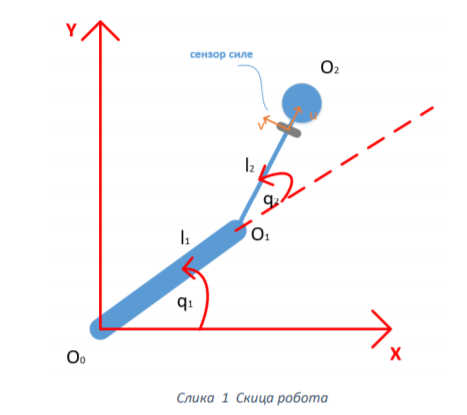

clear all
sympref('AbbreviateOutput',false);
syms l_1 l_2 q_1 q_2 m_1 m_2
x = l_1*cos(q_1)+l_2*cos(q_2+q_1)

$$x = l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)$$

y = l_1*sin(q_1)+l_2*sin(q_2+q_1)

$$y = l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)$$

J(1,1) = diff(x,q_1);
J(2,1) = diff(y,q_1);
J(1,2) = diff(x,q_2);
J(2,2) = diff(y,q_2);
J

$$J = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$


syms q_dot_1 q_dot_2 q_ddot_1 q_ddot_2
vx = diff(x,q_1)*q_dot_1+diff(x,q_2)*q_dot_2;
vy = diff(y,q_1)*q_dot_1+diff(y,q_2)*q_dot_2;
v2=simplify(sqrt(vx^2+vy^2));
Ek = simplify(1/6*m_1*(q_dot_1*l_1)^2+1/2*m_2*v2^2)

$$Ek = \frac{m_{2}\,\left({l_{1}}^{2}\,{{\dot{q}}_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}\,{{\dot{q}}_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{l_{2}}^{2}\,{{\dot{q}}_{1}}^{2}+2\,{l_{2}}^{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{l_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{{l_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}}{6}$$

L=Ek;

dL_ddq1 = diff(L,q_dot_1);
dL_ddq2 = diff(L,q_dot_2);

syms q_1(t) q_2(t)
q_1 = q_1(t);
q_2 = q_2(t);
q_dot_1 = diff(q_1,t);
q_dot_2 = diff(q_2,t);

eq1=simplify(diff(eval(dL_ddq1),t)-functionalDerivative(eval(L),q_1));
eq2=simplify(diff(eval(dL_ddq2),t)-functionalDerivative(eval(L),q_2));

collect(eq1,[diff(q_1,t,2) diff(q_2,t,2)] )

$$ans = \left(\frac{2\,{l_{1}}^{2}\,m_{1}}{3}+2\,{l_{1}}^{2}\,m_{2}+2\,{l_{2}}^{2}\,m_{2}+4\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+\left(2\,m_{2}\,{l_{2}}^{2}+2\,l_{1}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,l_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)-2\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2}-4\,l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)$$

collect(eq2,[diff(q_1,t,2) diff(q_2,t,2)] )

$$ans = \left(2\,m_{2}\,{l_{2}}^{2}+2\,l_{1}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,l_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{1}\left(t\right)+\left(2\,{l_{2}}^{2}\,m_{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}q_{2}\left(t\right)+l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}-l_{1}\,l_{2}\,m_{2}\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)$$


H(1,1)=subs(eq1,[diff(q_1,t,2),diff(q_1,t) diff(q_2,t,2),diff(q_2,t)],[1 0 0 0]);
H(1,2)=subs(eq1,[diff(q_1,t,2),diff(q_1,t) diff(q_2,t,2),diff(q_2,t)],[0 0 1 0]);
H(2,1)=subs(eq2,[diff(q_1,t,2),diff(q_1,t) diff(q_2,t,2),diff(q_2,t)],[1 0 0 0]);
H(2,2)=subs(eq2,[diff(q_1,t,2),diff(q_1,t) diff(q_2,t,2),diff(q_2,t)],[0 0 1 0]);
H

$$H = \left(\begin{array}{cc} \frac{2\,{l_{1}}^{2}\,m_{1}}{3}+2\,{l_{1}}^{2}\,m_{2}+2\,{l_{2}}^{2}\,m_{2}+4\,l_{1}\,l_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right) & 2\,m_{2}\,{l_{2}}^{2}+2\,l_{1}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,l_{2}\\ 2\,m_{2}\,{l_{2}}^{2}+2\,l_{1}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,l_{2} & 2\,{l_{2}}^{2}\,m_{2} \end{array}\right)$$